 
rng('default');

nSignals = 10000;
nSamples = 512;
dt = 0.5;
sigma = 1;

fs = 1/dt;
t = (0:nSamples-1)*dt;

% Choose scales/frequencies for CWT. Use analytic Morlet via cwt with
% sampling frequency to get frequencies directly.
% Precompute frequencies from a single cwt call to determine length.
[~,freqs] = cwt(randn(1,nSamples),'amor',fs);
nFreq = numel(freqs);

Fc_amor = centfrq('morl'); % approximate center freq for Morlet-like wavelet
scales = Fc_amor ./ (freqs * dt);


% Accumulator for power averaged over time, then over signals
acc_power = zeros(nFreq,1);

for k = 1:nSignals
    x = sigma*randn(1,nSamples);
    wt = cwt(x,'amor',fs); % complex coeffs: size nFreq x nSamples
    power = abs(wt).^2;    % instantaneous power
    time_avg_power = mean(power,2) .* scales; % average over time (columns)
    % MATLAB uses L1 normalization, with which CWT power scales as 1/scale
    % (of as frequency). Multiply the power with scales to make the power 
    % independent on scale (frequency). This basically converts the
    % normalization to L2
    acc_power = acc_power + time_avg_power;
end

avg_power_vs_freq = acc_power / nSignals;

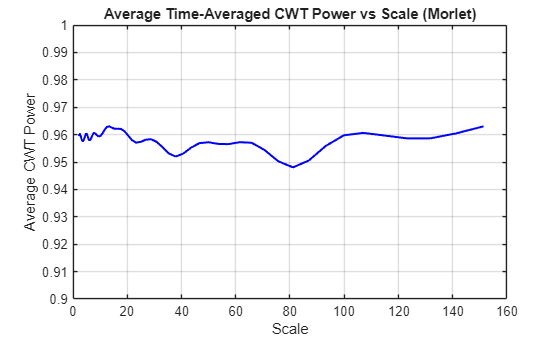


figure;
plot(scales, avg_power_vs_freq , '-b', 'LineWidth', 1.5);
xlabel('Scale');
ylabel('Average CWT Power');
title('Average Time-Averaged CWT Power vs Scale (Morlet)');
grid on;
ylim([0.9, 1.0])

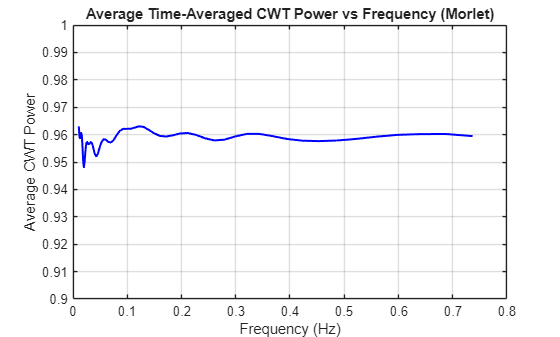

figure;
plot(freqs, avg_power_vs_freq , '-b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Average CWT Power');
title('Average Time-Averaged CWT Power vs Frequency (Morlet)');
grid on;
ylim([0.9, 1.0])

ans = 2

min(freqs), max(freqs)

ans = 0.0107

ans = 0.7366

### Morse wavelet

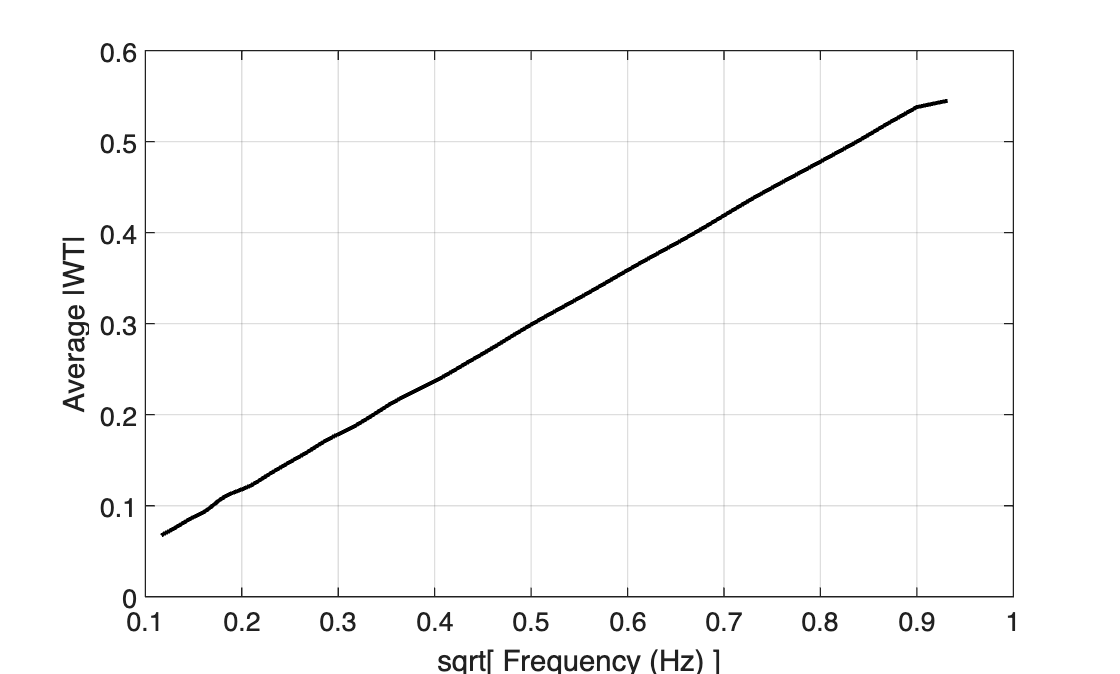

nSignals = 1000;
[~,freqs] = cwt(randn(1,nSamples),'morse',fs);
nFreq = numel(freqs);

acc = zeros(nFreq,1);

for k = 1:nSignals
    x = randn(1,nSamples);
    wt = cwt(x,'morse',fs);
    amp = abs(wt);
    amp_taver = mean(amp,2); % average over time (columns)
    acc = acc + amp_taver;
end

acc_mean = acc / nSignals;

figure;
plot(sqrt(freqs), acc_mean, '-k', 'LineWidth', 1.5);
xlabel('sqrt[ Frequency (Hz) ]');
ylabel('Average |WT|');
grid on;

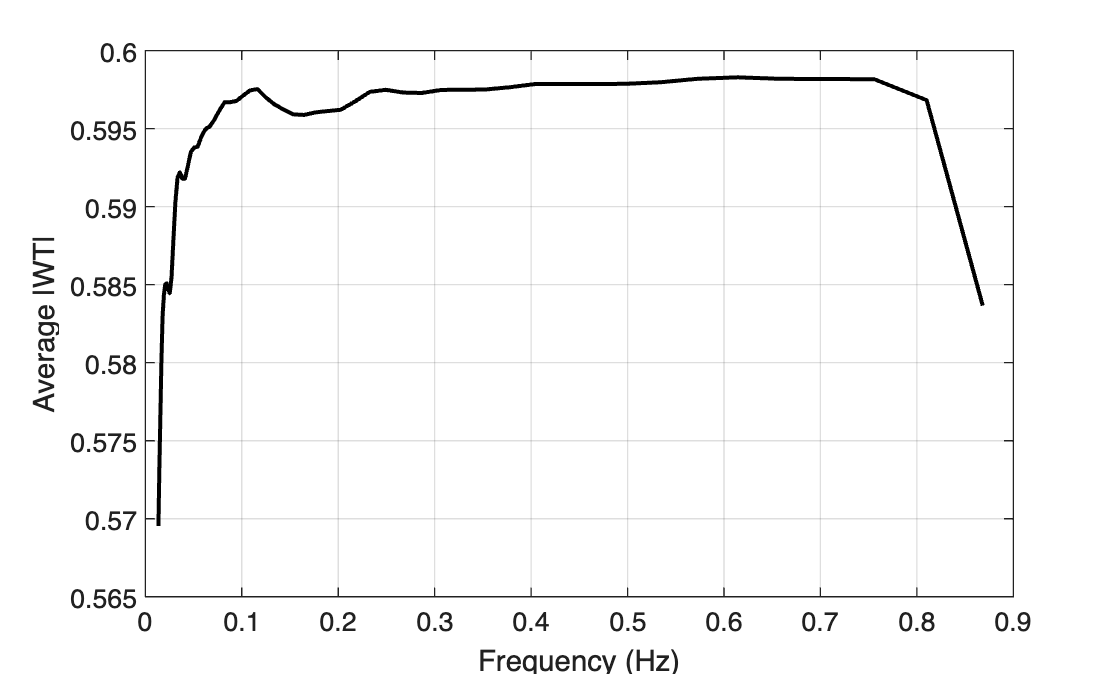

figure;
plot(freqs, acc_mean./sqrt(freqs), '-k', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Average |WT|');
grid on;